clearvars;

% Init param

max_rho = 1;
delta = 0.001;
E0_values = [];  % Pel display
rho_values = []; % Pel display
A_values = [];   % Pel display
H_values = [];

N = 20;
[z,w] = GaussHermite_Locations_Weights(N);

R = 0.5;
SNR = 1.0;

M = 2;
% Init param
% M = zeros(8, 1);
% for i = 1:length(M)
%     M(i) = 2^i;
% end


[x, q] = PAM_generator(M); % for equiprobable symbols
[Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);

Polinomio de Hermite:


$$\frac{373462012026285\,x^{3}}{18014398509481984}-\frac{3496958433984361\,x^{2}}{18014398509481984}+\frac{997312225808533\,x}{4503599627370496}$$

Máximo en rho = 0.63498, f(x) = 0.067653


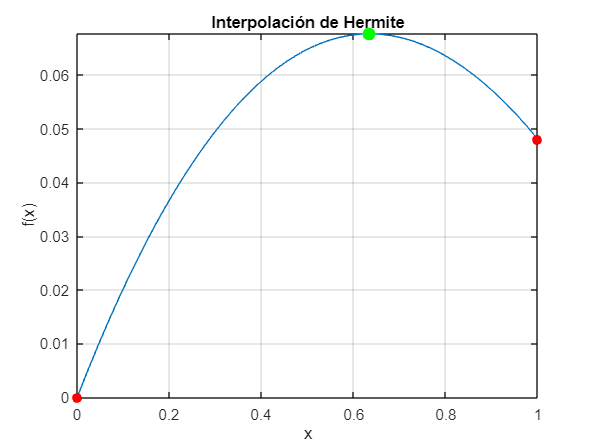

threshold = 1e-10;
max_iteracions = 100;

%disp(['Modulació: ', num2str(M(i))]);
tic;
best_rho = newton_method(x, SNR, Q, pi_, G, max_iteracions, threshold, R);

elapsed_time = toc;
disp(['Temps NM: ', num2str(elapsed_time), ' segons']);

Temps NM: 0.68518 segons


% % Newton method execution time
% threshold = 1e-10;
% max_iteracions = 100;
% 
% tic;
% best_rho = newton_method(x, SNR, Q, pi_, G, max_iteracions, threshold, R);
% elapsed_time = toc;
% 
% % rho on A es maxima:
% fprintf('Màxim trobat a rho = %.10f\n', best_rho);
% a_max = E0_matrix(Q, pi_, G, best_rho) - best_rho * R;
% disp(['A max value: ', num2str(a_max)]);
% 
% disp(['Temps NM: ', num2str(elapsed_time), ' segons']);

% % Trobar rho amb E0 i max()
% disp("---------------------------------------------------------")

---------------------------------------------------------


% rho = 0;
% tic;
% % E0 computation with matrices
% while rho <= max_rho
%     E0_i = E0_matrix(Q, pi_, G, rho);
%     A = E0_i - rho*R;
% 
%     E0_values = [E0_values, E0_i];      % Pel display
%     rho_values = [rho_values, rho];     % Pel display          
%     A_values = [A_values, A];
% 
%     rho = rho + delta;
% end
% 
% % Find rho - la manera cutre
% [max, idx]= max(A_values);
% best_rho = delta * idx;
% 
% elapsed_time = toc; % ------------------------------------------
% 
% % Results
% fprintf('Màxim trobat a rho = %.10f\n', best_rho);

Màxim trobat a rho = 0.6330000000


% disp(['A max value:', num2str(max)]);

A max value:0.067991


% 
% disp(['Temps execució amb max(): ', num2str(elapsed_time), ' segons']);

Temps execució amb max(): 0.21597 segons


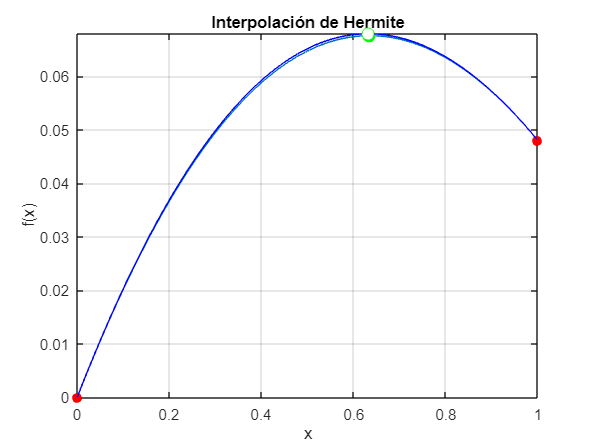

Polinomio de Hermite:


$$\frac{373462012026285\,x^{3}}{18014398509481984}-\frac{3496958433984361\,x^{2}}{18014398509481984}+\frac{997312225808533\,x}{4503599627370496}$$

Máximo en rho = 0.63498, f(x) = 0.067653


% 
% % Display -------------------------------------------------------------
% hold on
% plot(rho_values, A_values, 'b', 'DisplayName', 'E0 function');
% hold off
% 
% hold on;
% plot(best_rho, max, 'go', 'MarkerFaceColor', 'auto', 'MarkerSize', 8);
% hold off;

% % Gradient descent -----------------------------------------------------
% % Derivades en rho = 0
% [f, fp, f2p] = F0_matrix(Q, pi_, G, 0);
% gradient = -fp/(f*log(2))-R; % primera derivada
% curvatura = -(f2p/f - (fp/f)*(fp/f))/log(2); % segona derivada per definir alpha
% 
% % Gradient ascent execution time
% rho = 0.5;
% alpha = 1/curvatura; % 0.01, 0.05
% threshold = 1e-4;
% max_iteracions = 100;
% 
% tic;
% best_rho = gradient_ascent(Q, pi_, G, rho, alpha, max_iteracions, threshold, R);
% elapsed_time = toc;
% 
% % rho on A es maxima:
% fprintf('Màxim trobat a rho = %.10f\n', best_rho);
% a_max = E0_matrix(Q, pi_, G, best_rho) - best_rho * R;
% disp(['A max value: ', num2str(a_max)]);
% 
% disp(['Temps gradient descent: ', num2str(elapsed_time), ' segons']);